# Coaxial Variable-Tilt Multicopter

This document contains the specification calculations to determine the required propulsion system components given a several configuration parameters. 

## Multicopter Specifications:

###     Constants

g = 9.8;

###     Variables:

####             Design Goals:

% Thrust-to-weight ratio
TTW = 3; 

####             Multicopter parameters:

% Mass of the UAV
m = 5000; %g

% Number of rotors
r = 8;

% Coaxial rotor efficiency
n = 0.8;

% Rotor configuration
%rc = coaxial;


###     Design Objectives

% Hover Analysis
thrust_hover = m; %g
thrust_hover_rotor = thrust_hover/(4*(1+n)); %g

% Performance Analysis
thrust_max = m*TTW; %g
thrust_max_rotor = thrust_max/(4*(1+n)); %g

% Non-boundary
thrust_max_75 = thrust_max*0.75;
thrust_max_75_rotor = thrust_max_rotor*0.75;

colors = struct('WOT', [62 150 81] / 255, 'hover', [107 76 154] / 255, 'WOT75', [146 36 40] / 255);

## Sizing

###     Propeller

% Import propeller data
Propeller_name = 'APC 13x5.5MR'

Propeller_name = 'APC 13x5.5MR'

Propeller = {Propeller_name}

Propeller = 1×1 cell array
    {'APC 13x5.5MR'}


% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 11);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:K18";

% Specify column names and types
opts.VariableNames = ["RPM", "Thrust_LBF_", "Power_HP_", "Torque_In_LBF_", "Cp", "Ct", "FOM", "Thrust_N_", "Thrust_g_", "Torque_Nm_", "Power"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
propeller = readtable("C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\13x55MR.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

RPM_hover = interp1(propeller.Thrust_g_, propeller.RPM, thrust_hover_rotor)

RPM_hover = 4.2383e+03

RPM_WOT75 = interp1(propeller.Thrust_g_, propeller.RPM, thrust_max_75_rotor)

RPM_WOT75 = 6.3454e+03

RPM_WOT = interp1(propeller.Thrust_g_, propeller.RPM, thrust_max_rotor)

RPM_WOT = 7.3157e+03

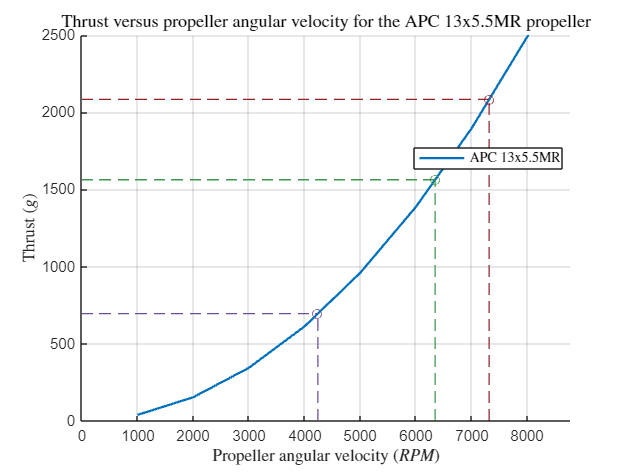


torque_hover = interp1(propeller.RPM, propeller.Torque_Nm_,RPM_hover);
torque_WOT75 = interp1(propeller.RPM, propeller.Torque_Nm_,RPM_WOT75);
torque_WOT = interp1(propeller.RPM, propeller.Torque_Nm_,RPM_WOT);

FOM_hover = interp1(propeller.RPM, propeller.FOM,RPM_hover);
FOM_WOT75 = interp1(propeller.RPM, propeller.FOM,RPM_WOT75);
FOM_WOT = interp1(propeller.RPM, propeller.FOM,RPM_WOT);

% Plot thrust versus RPM
figure, hold on
plot(propeller.RPM, propeller.Thrust_g_, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Thrust ($g$)', Interpreter='latex')
title('Thrust versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
operating_conditions(RPM_hover, thrust_hover_rotor, colors.hover);
operating_conditions(RPM_WOT75, thrust_max_75_rotor, colors.WOT);
operating_conditions(RPM_WOT, thrust_max_rotor, colors.WOT75);
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*thrust_max_rotor)]);
grid on
hold off

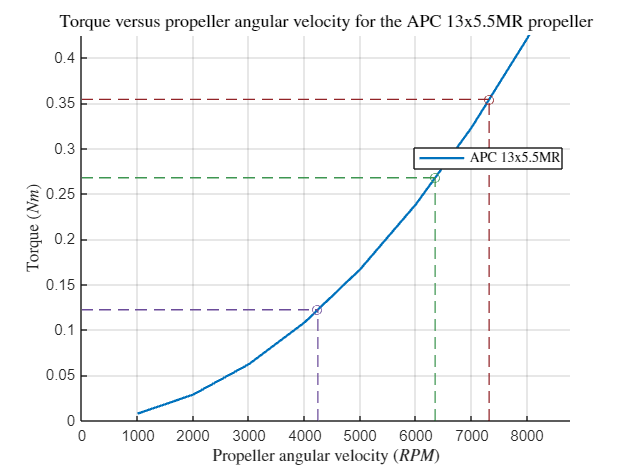


% Plot torque versus RPM
figure, hold on
plot(propeller.RPM, propeller.Torque_Nm_, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Torque ($Nm$)', Interpreter='latex')
title('Torque versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
operating_conditions(RPM_hover, torque_hover, colors.hover);
operating_conditions(RPM_WOT75, torque_WOT75, colors.WOT);
operating_conditions(RPM_WOT, torque_WOT, colors.WOT75);
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*torque_WOT)]);
legend(Location="best", Interpreter="latex")
grid on
hold off

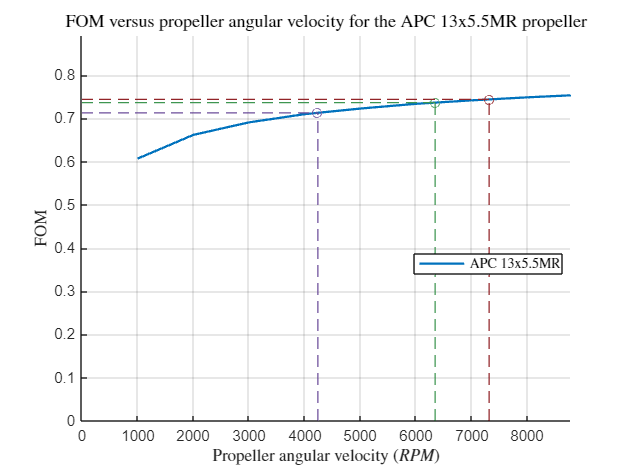


% Plot FOM vs RPM
figure, hold on
plot(propeller.RPM, propeller.FOM, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('FOM', Interpreter='latex')
title('FOM versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
operating_conditions(RPM_hover, FOM_hover, colors.hover);
operating_conditions(RPM_WOT75, FOM_WOT75, colors.WOT);
operating_conditions(RPM_WOT, FOM_WOT, colors.WOT75);
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*FOM_WOT)]);
grid on
hold off


operating_data = table(Propeller, RPM_hover, RPM_WOT75, RPM_WOT, thrust_hover_rotor,thrust_max_75_rotor, thrust_max_rotor, torque_hover, torque_WOT75, torque_WOT, FOM_hover, FOM_WOT75, FOM_WOT);
disp(operating_data)

       Propeller        RPM_hover    RPM_WOT75    RPM_WOT    thrust_hover_rotor    thrust_max_75_rotor    thrust_max_rotor    torque_hover    torque_WOT75    torque_WOT    FOM_hover    FOM_WOT75    FOM_WOT
    ________________    _________    _________    _______    __________________    ___________________    ________________    ____________    ____________    __________    _________    _________    _______

    {'APC 13x5.5MR'}     4238.3       6345.4      7315.7           694.44                1562.5                2083.3           0.12234         0

propellers_of_interest = {"C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\10x45MR.xlsx";
    "C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\10x55MR.xlsx";
    "C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\11x45MR.xlsx";
    "C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\12x55MR.xlsx";
    "C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\13x55MR.xlsx"};

propellers = {"10x4.5MR"; "10x5.5MR"; "11x4.5MR"; "12x4.5MR"; "13x4.5MR"}

propellers = 5×1 cell array
    {["10x4.5MR"]}
    {["10x5.5MR"]}
    {["11x4.5MR"]}
    {["12x4.5MR"]}
    {["13x4.5MR"]}


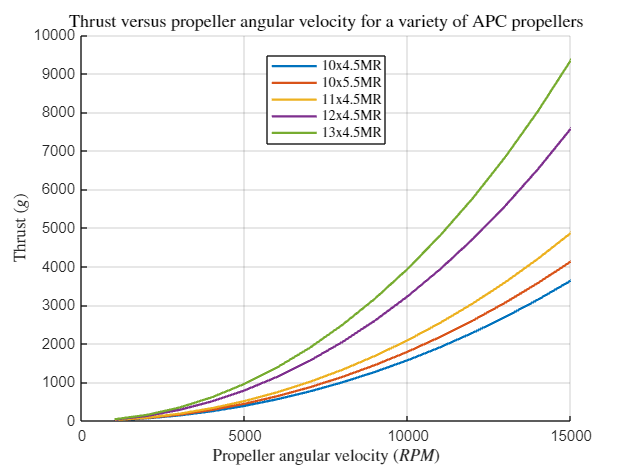


figure, hold on
for i = 1:length(propellers_of_interest)
    % Set up the Import Options and import the data
    opts = spreadsheetImportOptions("NumVariables", 11);
    
    % Specify sheet and range
    opts.Sheet = "Sheet1";
    opts.DataRange = "A2:K18";
    
    % Specify column names and types
    opts.VariableNames = ["RPM", "Thrust_LBF_", "Power_HP_", "Torque_In_LBF_", "Cp", "Ct", "FOM", "Thrust_N_", "Thrust_g_", "Torque_Nm_", "Power"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    
    % Import the data
    propeller = readtable(propellers_of_interest{i}, opts, "UseExcel", false);
    
    % Clear temporary variables
    clear opts

    plot(propeller.RPM, propeller.Thrust_g_, DisplayName=propellers{i}, LineWidth=1.5);
end

xlim([0 15000])
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Thrust ($g$)', Interpreter='latex')
title('Thrust versus propeller angular velocity for a variety of APC propellers', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
grid on
hold off

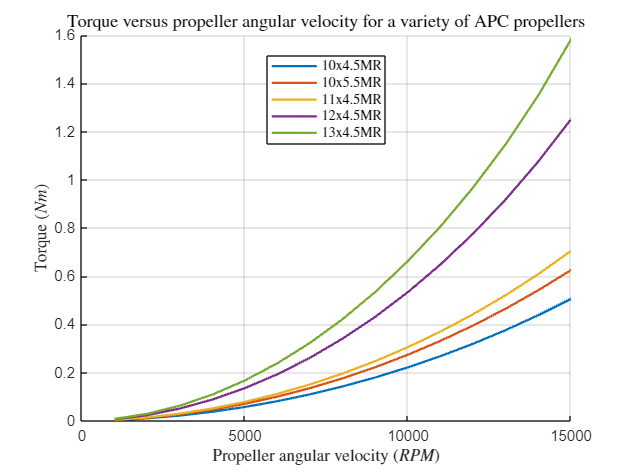


figure, hold on
for i = 1:length(propellers_of_interest)
    % Set up the Import Options and import the data
    opts = spreadsheetImportOptions("NumVariables", 11);
    
    % Specify sheet and range
    opts.Sheet = "Sheet1";
    opts.DataRange = "A2:K18";
    
    % Specify column names and types
    opts.VariableNames = ["RPM", "Thrust_LBF_", "Power_HP_", "Torque_In_LBF_", "Cp", "Ct", "FOM", "Thrust_N_", "Thrust_g_", "Torque_Nm_", "Power"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    
    % Import the data
    propeller = readtable(propellers_of_interest{i}, opts, "UseExcel", false);
    
    % Clear temporary variables
    clear opts

    plot(propeller.RPM, propeller.Torque_Nm_, DisplayName=propellers{i}, LineWidth=1.5);
end

xlim([0 15000])
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Torque ($Nm$)', Interpreter='latex')
title('Torque versus propeller angular velocity for a variety of APC propellers', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
grid on
hold off

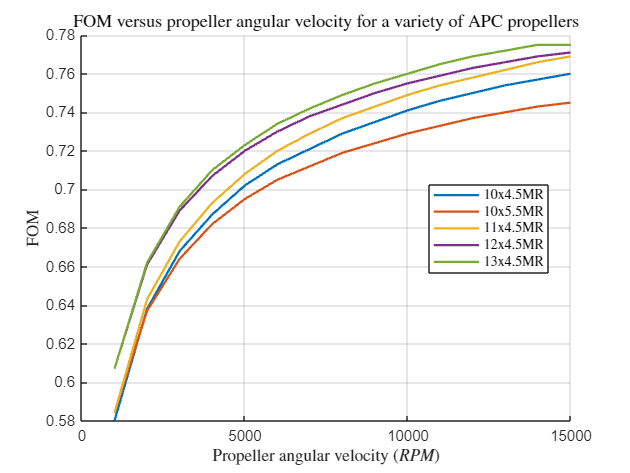


figure, hold on
for i = 1:length(propellers_of_interest)
    % Set up the Import Options and import the data
    opts = spreadsheetImportOptions("NumVariables", 11);
    
    % Specify sheet and range
    opts.Sheet = "Sheet1";
    opts.DataRange = "A2:K18";
    
    % Specify column names and types
    opts.VariableNames = ["RPM", "Thrust_LBF_", "Power_HP_", "Torque_In_LBF_", "Cp", "Ct", "FOM", "Thrust_N_", "Thrust_g_", "Torque_Nm_", "Power"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    
    % Import the data
    propeller = readtable(propellers_of_interest{i}, opts, "UseExcel", false);
    
    % Clear temporary variables
    clear opts

    plot(propeller.RPM, propeller.FOM, DisplayName=propellers{i}, LineWidth=1.5);
end

xlim([0 15000])
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('FOM', Interpreter='latex')
title('FOM versus propeller angular velocity for a variety of APC propellers', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
grid on
hold off

###     Motor

% Motor specifications
Battery_voltage = 14.8; 

motors = readtable("C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\BLDC Motor Database.xlsx")

motors = 102×21 table
       Brand           Name         Diameter    Height     Kv       Rm       Io     IoV     Weight    Cost                                    Link                                       Var12       kvRad     qm_Kv     Var15      Var16     Var17       DC       DC_0_2       Var20         Var21   
    ___________    _____________    ________    ______    ____    ______    ____    ____    ______    ____    ______________________________________

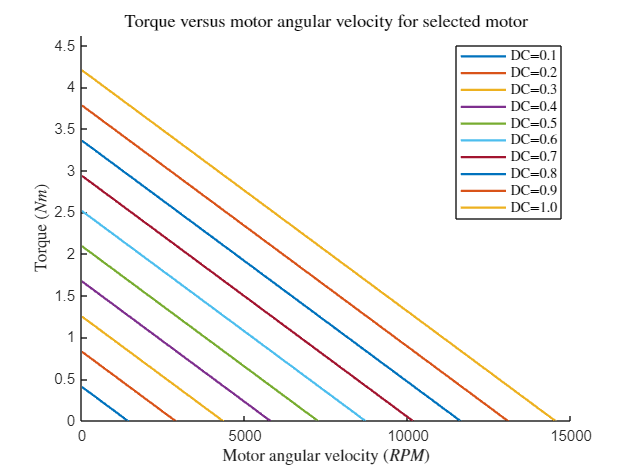


selected_motor = 13;

% Motor specifications 
Kv = motors.Kv(selected_motor)*(2*pi/60);
Rm = motors.Rm(selected_motor);
I0 = motors.Io(selected_motor);
I0V = motors.IoV(selected_motor);

DC = linspace(0.1,1,10);
speed = linspace(0, Battery_voltage*Kv, 500);

% Plot torque versus motor angular velocity for a variety of duty cycles
figure, hold on
for i = 1:length(DC)
    v = (Battery_voltage*DC(i));
    torque = ((v-(speed./Kv))*(1/Rm)-I0)*(1/Kv);
    plot(speed*(60/(2*pi)), torque, 'DisplayName', sprintf('DC=%.1f', DC(i)), LineWidth=1.5);
end
ylim([0 1.1*max(torque)])
hold off
xlabel('Motor angular velocity ($RPM$)', Interpreter='latex')
ylabel('Torque ($Nm$)', Interpreter='latex')
title('Torque versus motor angular velocity for selected motor', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")

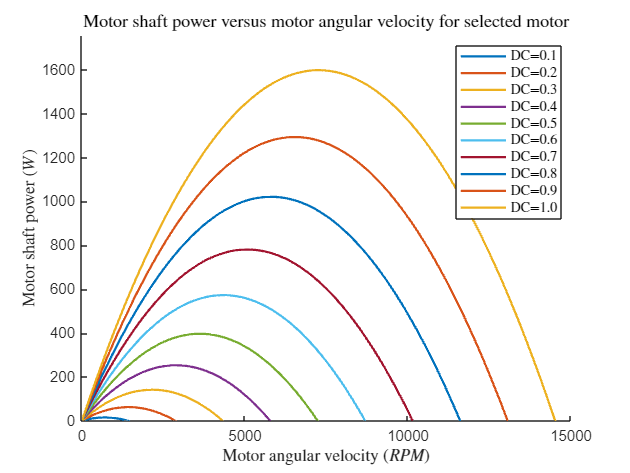


% Plot motor shaft power versus motor angular velocity for a variety of duty cycles
figure, hold on
for i = 1:length(DC)
    v = (Battery_voltage*DC(i));
    power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv);
    plot(speed*(60/(2*pi)), power, 'DisplayName', sprintf('DC=%.1f', DC(i)), LineWidth=1.5);
end
ylim([0 1.1*max(power)])
hold off
xlabel('Motor angular velocity ($RPM$)', Interpreter='latex')
ylabel('Motor shaft power ($W$)', Interpreter='latex')
title('Motor shaft power versus motor angular velocity for selected motor', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")

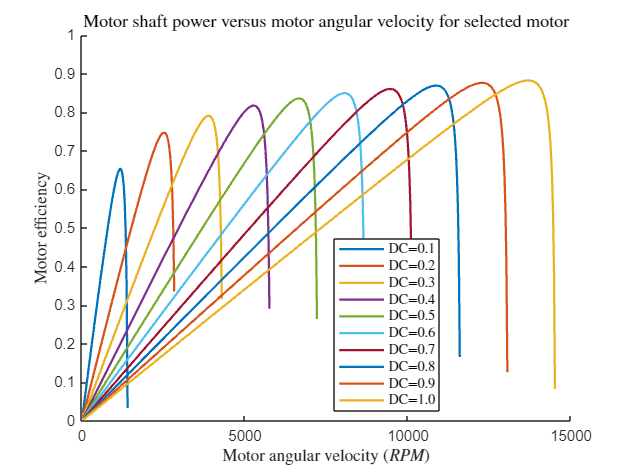


figure, hold on
    for i = 1:length(DC)
        speed = linspace(0, Battery_voltage*Kv, 500);
        v = (Battery_voltage*DC(i));
        power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv); 
        efficiency = (1-(I0*Rm)./(v-(speed./Kv))).*(speed./(v*Kv));
        cut = power > 0 & efficiency> 0;
        speed = speed(cut);
        efficiency = efficiency(cut);
        plot(speed*(60/(2*pi)), efficiency, 'LineWidth', 1.5, 'DisplayName', sprintf('DC=%.1f', DC(i)), LineWidth=1.5);
    end
ylim([0 1])
hold off
xlabel('Motor angular velocity ($RPM$)', Interpreter='latex')
ylabel('Motor efficiency', Interpreter='latex')
title('Motor shaft power versus motor angular velocity for selected motor', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")

###     Propeller and motor matching

% Import propeller data
Propeller_name = 'APC 13x5.5MR'

Propeller_name = 'APC 13x5.5MR'

Propeller = {Propeller_name}

Propeller = 1×1 cell array
    {'APC 13x5.5MR'}


% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 11);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:K18";

% Specify column names and types
opts.VariableNames = ["RPM", "Thrust_LBF_", "Power_HP_", "Torque_In_LBF_", "Cp", "Ct", "FOM", "Thrust_N_", "Thrust_g_", "Torque_Nm_", "Power"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
propeller = readtable("C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\13x55MR.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Motor specifications
Battery_voltage = 14.8; 

motors = readtable("C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\BLDC Motor Database.xlsx")

motors = 102×21 table
       Brand           Name         Diameter    Height     Kv       Rm       Io     IoV     Weight    Cost                                    Link                                       Var12       kvRad     qm_Kv     Var15      Var16     Var17       DC       DC_0_2       Var20         Var21   
    ___________    _____________    ________    ______    ____    ______    ____    ____    ______    ____    ______________________________________


selected_motor = 13;

% Motor specifications 
Kv = motors.Kv(selected_motor)*(2*pi/60)

Kv = 103.1490

Rm = motors.Rm(selected_motor)

Rm = 0.0340

I0 = motors.Io(selected_motor)

I0 = 1.6000

I0V = motors.IoV(selected_motor)

I0V = 11.1000


DC = linspace(0.1,1,10);
speed = linspace(0, Battery_voltage*Kv, 500);


RPM_hover = interp1(propeller.Thrust_g_, propeller.RPM, thrust_hover_rotor);
RPM_WOT75 = interp1(propeller.Thrust_g_, propeller.RPM, thrust_max_75_rotor);
RPM_WOT = interp1(propeller.Thrust_g_, propeller.RPM, thrust_max_rotor);

torque_hover = interp1(propeller.RPM, propeller.Torque_Nm_,RPM_hover);
torque_WOT75 = interp1(propeller.RPM, propeller.Torque_Nm_,RPM_WOT75);
torque_WOT = interp1(propeller.RPM, propeller.Torque_Nm_,RPM_WOT);

FOM_hover = interp1(propeller.RPM, propeller.FOM,RPM_hover);
FOM_WOT75 = interp1(propeller.RPM, propeller.FOM,RPM_WOT75);
FOM_WOT = interp1(propeller.RPM, propeller.FOM,RPM_WOT);


% Plot thrust versus RPM
figure, hold on
plot(propeller.RPM, propeller.Thrust_g_, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Thrust ($g$)', Interpreter='latex')
title('Thrust versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
operating_conditions(RPM_hover, thrust_hover_rotor, colors.hover);
operating_conditions(RPM_WOT75, thrust_max_75_rotor, colors.WOT);
operating_conditions(RPM_WOT, thrust_max_rotor, colors.WOT75);
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*thrust_max_rotor)]);
grid on
hold off

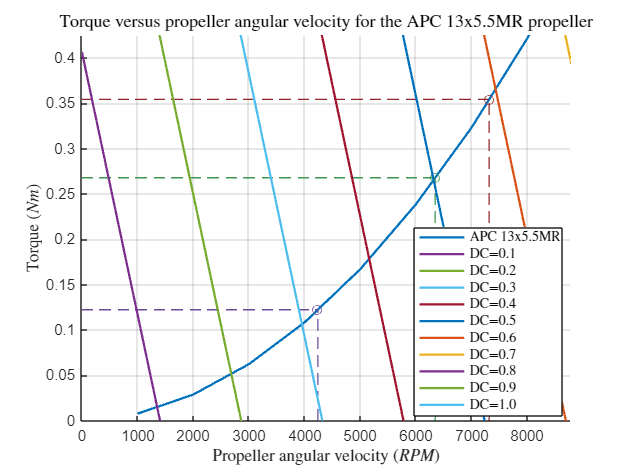


% Plot torque versus RPM
figure, hold on
plot(propeller.RPM, propeller.Torque_Nm_, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Torque ($Nm$)', Interpreter='latex')
title('Torque versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
operating_conditions(RPM_hover, torque_hover, colors.hover);
operating_conditions(RPM_WOT75, torque_WOT75, colors.WOT);
operating_conditions(RPM_WOT, torque_WOT, colors.WOT75);
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*torque_WOT)]);
for i = 1:length(DC)
    v = (Battery_voltage*DC(i));
    torque = ((v-(speed./Kv))*(1/Rm)-I0)*(1/Kv);
    plot(speed*(60/(2*pi)), torque, 'DisplayName', sprintf('DC=%.1f', DC(i)), LineWidth=1.5);
end
legend(Location="best", Interpreter="latex")
grid on
hold off

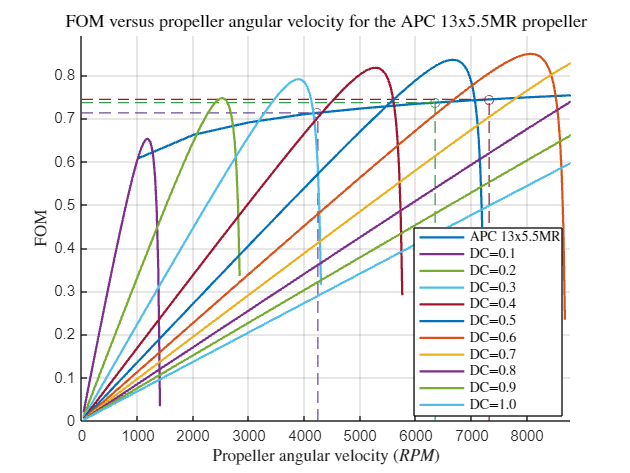


% Plot FOM vs RPM
figure, hold on
plot(propeller.RPM, propeller.FOM, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('FOM', Interpreter='latex')
title('FOM versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
operating_conditions(RPM_hover, FOM_hover, colors.hover);
operating_conditions(RPM_WOT75, FOM_WOT75, colors.WOT);
operating_conditions(RPM_WOT, FOM_WOT, colors.WOT75);
for i = 1:length(DC)
        speed = linspace(0, Battery_voltage*Kv, 500);
        v = (Battery_voltage*DC(i));
        power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv); 
        efficiency = (1-(I0*Rm)./(v-(speed./Kv))).*(speed./(v*Kv));
        cut = power > 0 & efficiency> 0;
        speed = speed(cut);
        efficiency = efficiency(cut);
        plot(speed*(60/(2*pi)), efficiency, 'LineWidth', 1.5, 'DisplayName', sprintf('DC=%.1f', DC(i)), LineWidth=1.5);
end
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*FOM_WOT)]);
grid on
hold off


DC_needed_WOT = ((Kv*torque_WOT+I0)*Rm+(RPM_WOT*2*pi/60)/Kv)/Battery_voltage

DC_needed_WOT = 0.5894

DC_needed_WOT75 = ((Kv*torque_WOT75+I0)*Rm+(RPM_WOT75*2*pi/60)/Kv)/Battery_voltage

DC_needed_WOT75 = 0.5024

DC_needed_hover = ((Kv*torque_hover+I0)*Rm+(RPM_hover*2*pi/60)/Kv)/Battery_voltage

DC_needed_hover = 0.3234

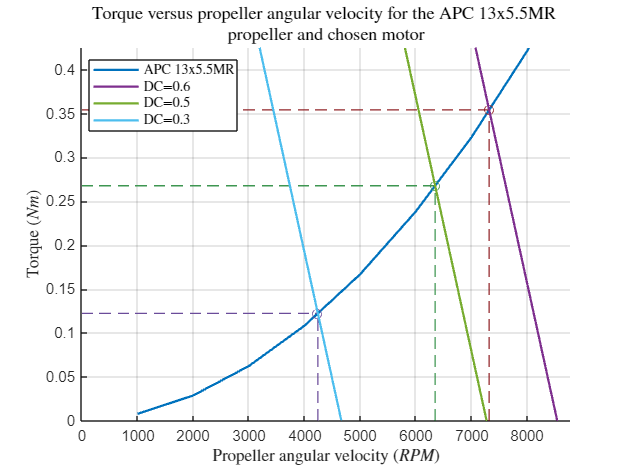


% Plot torque versus RPM
figure, hold on
plot(propeller.RPM, propeller.Torque_Nm_, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Torque ($Nm$)', Interpreter='latex')
title({'Torque versus propeller angular velocity for the APC 13x5.5MR '; ...
    'propeller and chosen motor'}, Interpreter='latex', FontSize=12)
operating_conditions(RPM_hover, torque_hover, colors.hover);
operating_conditions(RPM_WOT75, torque_WOT75, colors.WOT);
operating_conditions(RPM_WOT, torque_WOT, colors.WOT75);
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*torque_WOT)]);
v = (Battery_voltage*DC_needed_WOT);
speed = linspace(0, Battery_voltage*Kv, 500);
torque = ((v-(speed./Kv))*(1/Rm)-I0)*(1/Kv);
plot(speed*(60/(2*pi)), torque, 'DisplayName', sprintf('DC=%.1f', DC_needed_WOT), LineWidth=1.5);
v = (Battery_voltage*DC_needed_WOT75);
torque = ((v-(speed./Kv))*(1/Rm)-I0)*(1/Kv);
plot(speed*(60/(2*pi)), torque, 'DisplayName', sprintf('DC=%.1f', DC_needed_WOT75), LineWidth=1.5);
v = (Battery_voltage*DC_needed_hover);
torque = ((v-(speed./Kv))*(1/Rm)-I0)*(1/Kv);
plot(speed*(60/(2*pi)), torque, 'DisplayName', sprintf('DC=%.1f', DC_needed_hover), LineWidth=1.5);
legend(Location="best", Interpreter="latex")
grid on
hold off

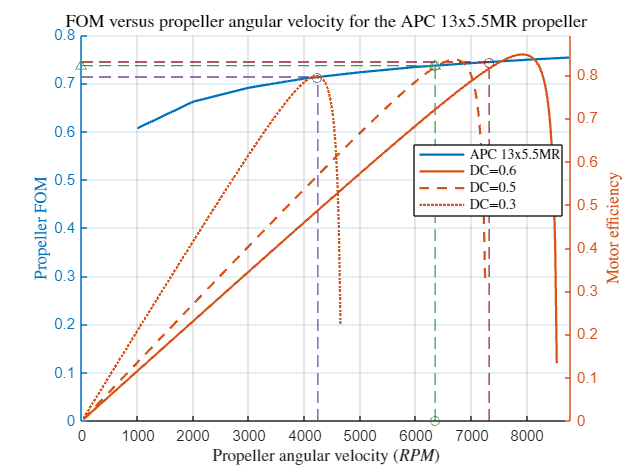


% Plot FOM vs RPM
figure, hold on
yyaxis left
plot(propeller.RPM, propeller.FOM, DisplayName=Propeller_name, LineWidth=1.5)
xlabel('Propeller angular velocity ($RPM$)', Interpreter='latex')
ylabel('Propeller FOM', Interpreter='latex')
title('FOM versus propeller angular velocity for the APC 13x5.5MR propeller', Interpreter='latex', FontSize=12)
legend(Location="best", Interpreter="latex")
operating_conditions(RPM_hover, FOM_hover, colors.hover);
operating_conditions(RPM_WOT75, FOM_WOT75, colors.WOT);
operating_conditions(RPM_WOT, FOM_WOT, colors.WOT75);
yyaxis right
ylabel('Motor efficiency', Interpreter='latex')
for i = 1:length(DC_needed_WOT)
        speed = linspace(0, Battery_voltage*Kv, 500);
        v = (Battery_voltage*DC_needed_WOT);
        power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv); 
        efficiency = (1-(I0*Rm)./(v-(speed./Kv))).*(speed./(v*Kv));
        cut = power > 0 & efficiency> 0;
        speed = speed(cut);
        efficiency = efficiency(cut);
        plot(speed*(60/(2*pi)), efficiency, 'LineWidth', 1.5, 'DisplayName', sprintf('DC=%.1f', DC_needed_WOT), LineWidth=1.5);
end
for i = 1:length(DC_needed_WOT75)
        speed = linspace(0, Battery_voltage*Kv, 500);
        v = (Battery_voltage*DC_needed_WOT75);
        power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv); 
        efficiency = (1-(I0*Rm)./(v-(speed./Kv))).*(speed./(v*Kv));
        cut = power > 0 & efficiency> 0;
        speed = speed(cut);
        efficiency = efficiency(cut);
        plot(speed*(60/(2*pi)), efficiency, 'LineWidth', 1.5, 'DisplayName', sprintf('DC=%.1f', DC_needed_WOT75), LineWidth=1.5);
end
for i = 1:length(DC_needed_hover)
        speed = linspace(0, Battery_voltage*Kv, 500);
        v = (Battery_voltage*DC_needed_hover);
        power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv); 
        efficiency = (1-(I0*Rm)./(v-(speed./Kv))).*(speed./(v*Kv));
        cut = power > 0 & efficiency> 0;
        speed = speed(cut);
        efficiency = efficiency(cut);
        plot(speed*(60/(2*pi)), efficiency, 'LineWidth', 1.5, 'DisplayName', sprintf('DC=%.1f', DC_needed_hover), LineWidth=1.5);
end
xlim([0 max(1.2*RPM_WOT)]);
ylim([0 max(1.2*FOM_WOT)]);
grid on
hold off

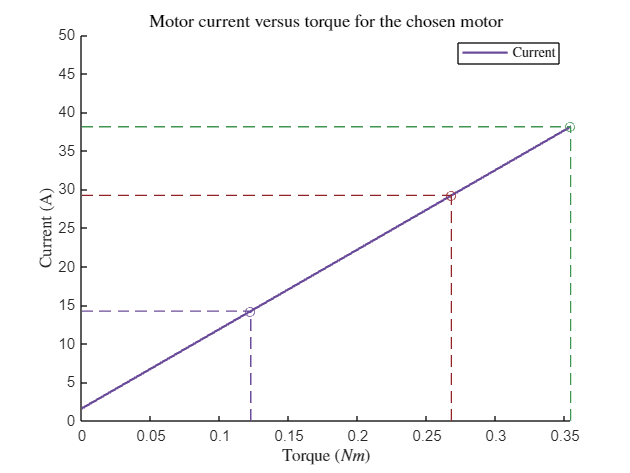

figure, hold on
for i = 1:length(DC)
        speed = linspace(0, Battery_voltage*Kv, 500);
        v = (Battery_voltage*DC(i));
        power = ((v-(speed./Kv))*(1/Rm)-I0).*(speed./Kv); 
        torque = ((v-(speed./Kv))*(1/Rm)-I0)*(1/Kv);
        current = (v-(speed/Kv))*(1/Rm);
        plot(torque, current, 'LineWidth', 1.5, LineWidth=1.5, Color=colors.hover);
end
xlim([0 torque_WOT])
ylim([0 50])
xlabel('Torque ($Nm$)', Interpreter='latex')
ylabel('Current (A)', Interpreter='latex')
title('Motor current versus torque for the chosen motor', Interpreter='latex', FontSize=12)
legend("Current", Location="best", Interpreter="latex")
v = (Battery_voltage*DC_needed_hover);
speed_hover = (RPM_hover*2*pi/60);
current_hover = (v-(speed_hover/Kv))*(1/Rm);
v = (Battery_voltage*DC_needed_WOT75);
speed_WOT75 = (RPM_WOT75*2*pi/60);
current_WOT75 = (v-(speed_WOT75/Kv))*(1/Rm);
v = (Battery_voltage*DC_needed_WOT);
speed_WOT = (RPM_WOT*2*pi/60);
current_WOT = (v-(speed_WOT/Kv))*(1/Rm);
operating_conditions(torque_hover, current_hover, colors.hover);
operating_conditions(torque_WOT75, current_WOT75, colors.WOT75);
operating_conditions(torque_WOT, current_WOT, colors.WOT);
hold off

###     Battery

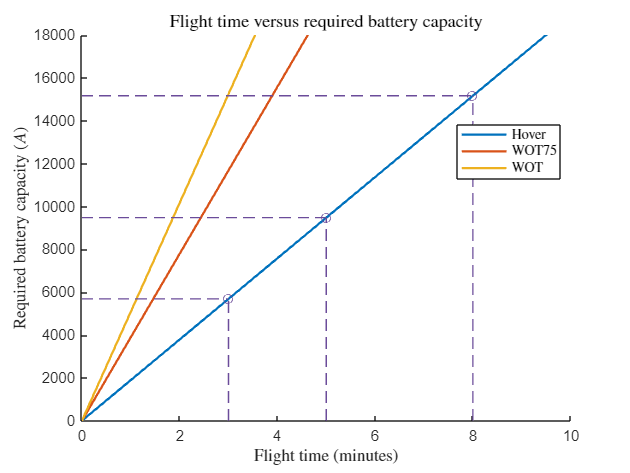

flight_time = 0:1:25;
Battery_voltage;
v = (Battery_voltage*DC_needed_hover);
speed_hover = RPM_hover*2*pi/60;
current_hover = (v-(speed_hover/Kv))*(1/Rm);
capacity_hover = 1000*8*current_hover*flight_time/60;
v = (Battery_voltage*DC_needed_WOT75);
speed_WOT75 = RPM_WOT75*2*pi/60;
current_WOT75 = (v-(speed_WOT75/Kv))*(1/Rm);
capacity_WOT75 = 1000*8*current_WOT75*flight_time/60;
v = (Battery_voltage*DC_needed_WOT);
speed_WOT75 = RPM_WOT75*2*pi/60;
current_WOT = (v-(speed_WOT/Kv))*(1/Rm);
capacity_WOT = 1000*8*current_WOT*flight_time/60;


figure, hold on
plot(flight_time, capacity_hover, 'LineWidth', 1.5, 'DisplayName', "Hover", LineWidth=1.5);
plot(flight_time, capacity_WOT75, 'LineWidth', 1.5, 'DisplayName', "WOT75", LineWidth=1.5);
plot(flight_time, capacity_WOT, 'LineWidth', 1.5, 'DisplayName', "WOT", LineWidth=1.5);
operating_conditions(3, interp1(flight_time, capacity_hover, 3), colors.hover);
operating_conditions(5, interp1(flight_time, capacity_hover, 5), colors.hover);
operating_conditions(8, interp1(flight_time, capacity_hover, 8), colors.hover);
ax = gca;
ax.YAxis.Exponent = 0;
ylim([0 18000])
xlabel('Flight time (minutes)', Interpreter='latex')
ylabel('Required battery capacity ($A$)', Interpreter='latex')
title('Flight time versus required battery capacity', Interpreter='latex', FontSize=12)
legend("Hover", "WOT75", "WOT", Interpreter='latex', location = "best")


required_flight_time = 5;
C_rating = 8*current_WOT/(interp1(flight_time, capacity_hover, required_flight_time)/1000)

C_rating = 32.1747


batteries = readtable("C:\Users\guyha\OneDrive\Documentos\The HOLY GUACOMOLE\MRAV Sizing\LiPo Battery Database.xlsx")

batteries = 125×10 table
       Brand        Capacity    Cell    C_rating    Weight      Dimensions      Cost                                                                 Link                                                                    Var9         Var10   
    ____________    ________    ____    ________    ______    ______________    ____    ______________________________________________________________________________________________________________________________    __________    __________

    {'Tattu'   }      5000       3         25        460      {'130x40x28' }    970     {'Gens ace 5000mAh 3S 25C Lipo Battery Pack Goblin Hobbies E

function operating_conditions = operating_conditions(x,y, colour)
plot([x, x], [0, y], HandleVisibility="off", LineStyle="--", Color=colour);
plot([0, x], [y, y], HandleVisibility="off", LineStyle="--", Color=colour);
plot(x, y, HandleVisibility="off", Marker="o", Color=colour);
end
